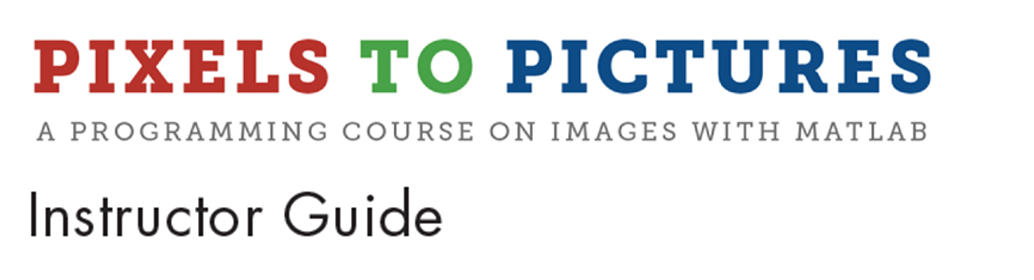

# Module 11: Text on Images

**Prerequisite Domain Knowledge:** None

**Expected Completion Time: **60 minutes

## **Recognizing Text in Images**

*Expected Duration: 20 minutes*

### Learning Objectives

- Text in images is recognized by analyzing light and dark areas in the image to identify each alphabetic letter or numeric digit. 

- Text needs to have a solid background for MATLAB to read it

- A region of interest (ROI) can be selected in an image where MATLAB ignores everything in the image apart from the ROI.

### Materials

- MATLAB®

### **Steps**

Tell the students that we will be talking about images that have text in them. 

In the **Command Window** in MATLAB, type:

This will open the Image Viewer App with a simple image that has just the words ‘Hello there!’ in it. 

Students can now explore the pixel values of the image, especially for the text. It should just be like any other image and have RGB values.

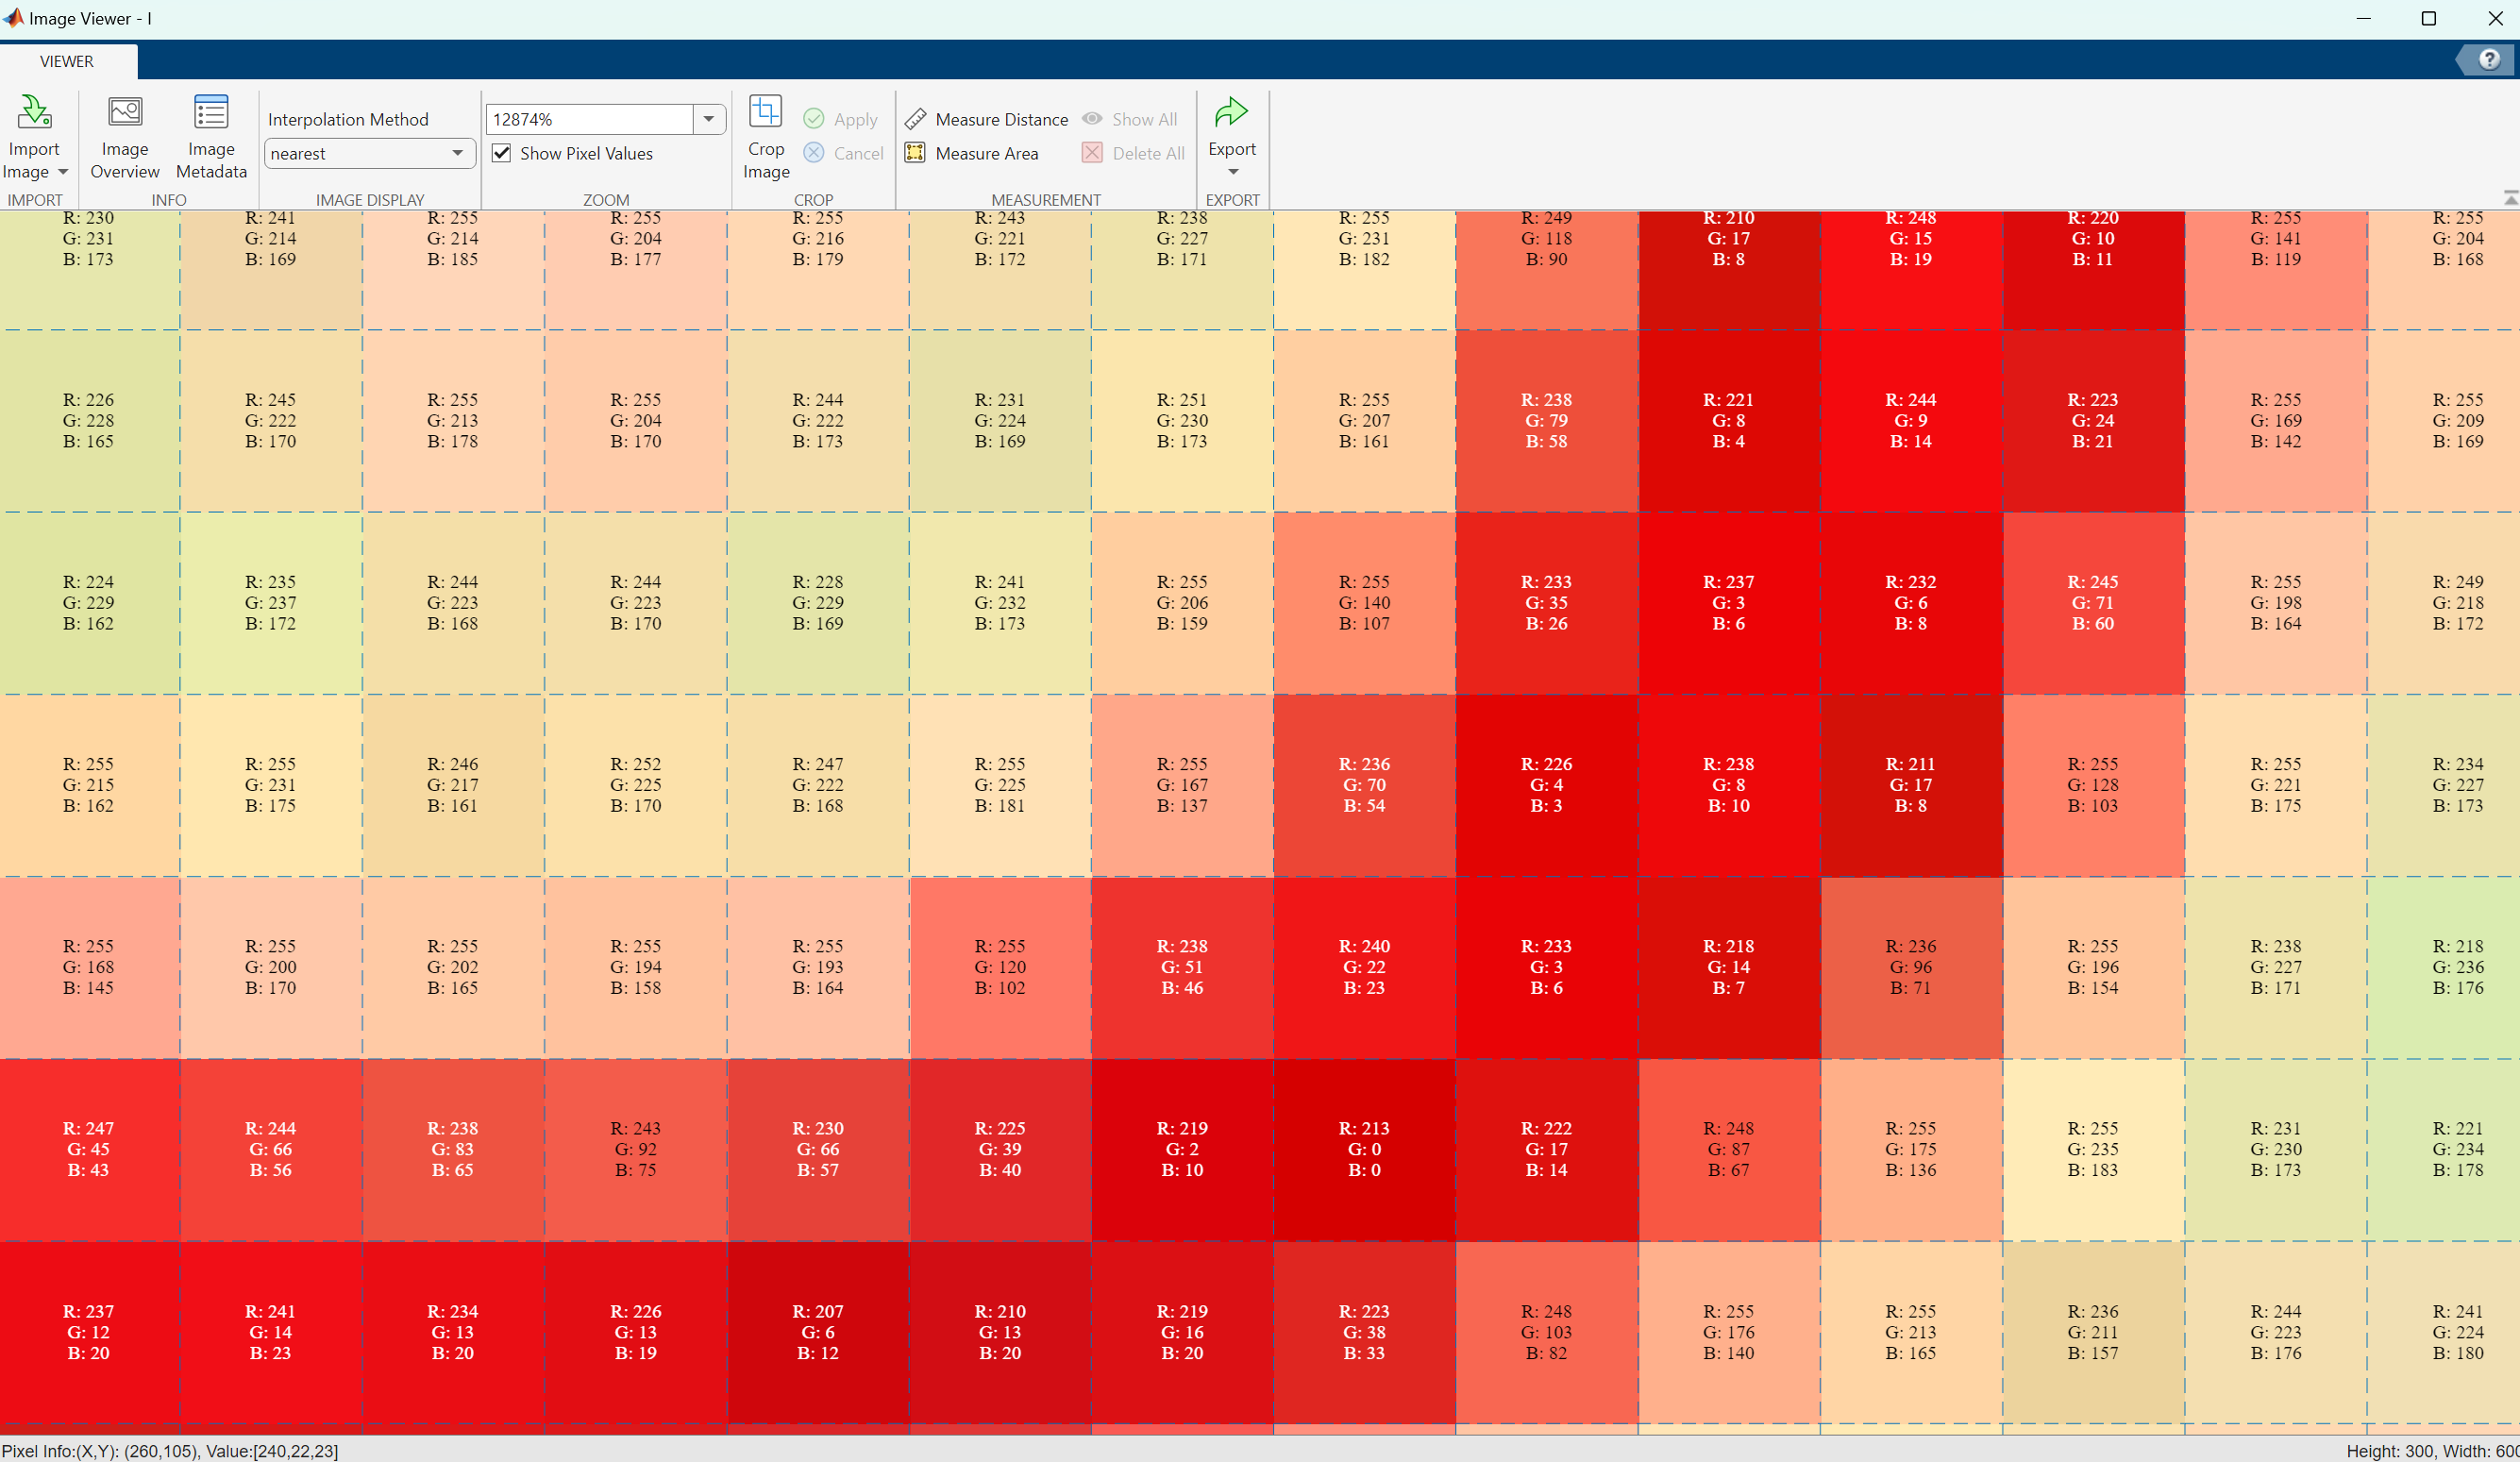

As humans, our eyes can see text in an image and immediately read it. 

Ask:

- **But can computers read text from images as well?**  

-     Encourage student to think about applications where computers can recognize text from images. Some examples are: 

- There are machines on the toll highways that can see your car’s license plate number and know whom the car belongs to and charge toll accordingly.

- ATM machines accept cash and check deposits by reading the number in value in the cash notes and the text in the check.

- Self-driving cars need to read road signs (STOP, YIELD) and act accordingly.

So if all a computer sees in an image is a bunch of pixels with RGB values, how are they able to distinguish text?

People over the years have been training computers to recognize text by using hundreds of different images of the same alphabet and letting the computer determine a pattern for the images its seeing. For example, in case of the letter ‘H’, after seeing many different kinds of ‘H’, the computer knows that if it sees a pattern similar to two parallel lines (equal size) with a short perpendicular line joining them in the middle, the pattern matches that of the letter ‘H’. 

Computers are very good at looking for patterns and very quick at it. They analyze the light and dark areas in the image to see if the pattern matches any of the known alphabets or numbers. For the example of letter ‘H’, the background color pixels contrast distinctly with the foreground pixels in the particular pattern mentioned above and the computer knows it is looking at the alphabet ‘H’.

 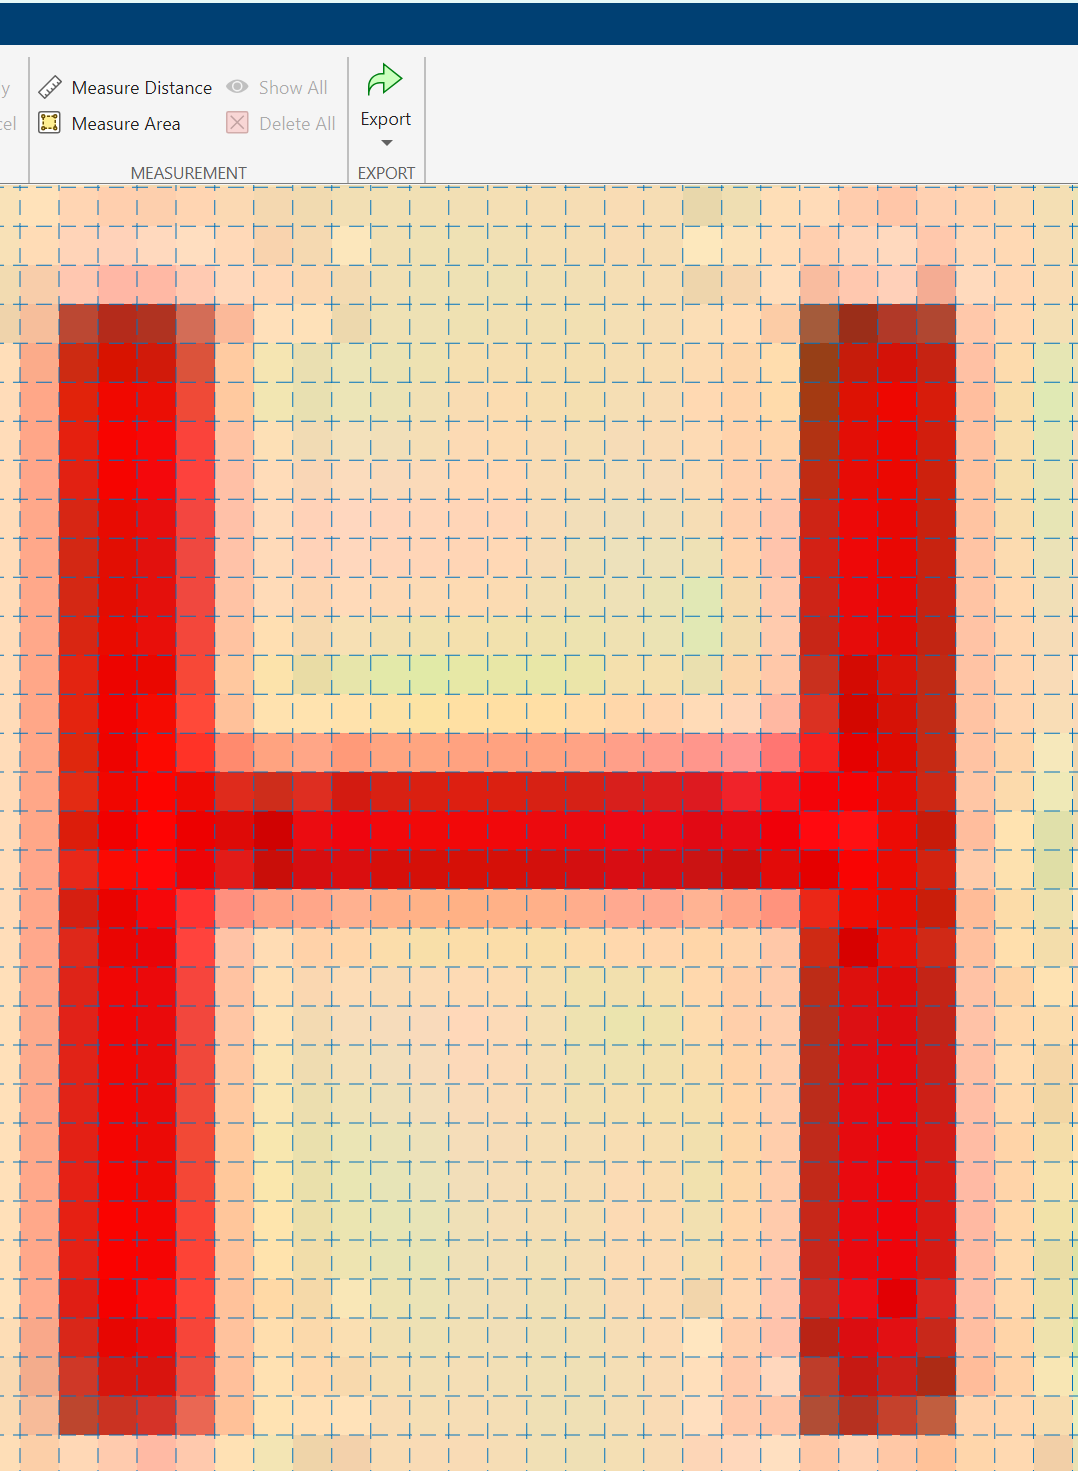

Give them an example of the pattern of the letter ‘A’, which is similar to ‘H’ since it also has two long lines and a short line joining them in the middle. However, the pattern differs because for ‘H’, the long lines are parallel, but for ‘A’, the lines slant towards each other till the tip meets. Similarly, each alphabet has a particular pattern that the computer knows to look for. 

Ask them to try a function called `readtext` to see if MATLAB can read the text in the image.

 

Ask the students to try out another example, by reading in the image ‘insects.jpg’ using the `readtext` function on it

 

They can view the image using `imshow` to check if it read the message correctly.

## Writing Text on Images

*Expected Duration: 30 minutes*

### Learning Objectives

- Write text on images using MATLAB

### Materials

- MATLAB®

### **Steps**

Let the students know that we can not only read text from images, but also write text on images - to create memes!

Ask the students to open the following script:

 
open 'TextOnImages.mlx'

The first line of code says:

This creates a blank white page of 100 rows and 400 columns.

Next they will use the `writetext` function to write on the blank page:

Have the students run the script.

This will show the blank white page and the mouse pointer will change to a large cross. You can use the center of the cross to select where the text will appear.  After displaying the text, ask:

- *What might be some ways that you would want to customize this text?  *

-     Students may mention characteristics like font size, font color, background color, etc.

 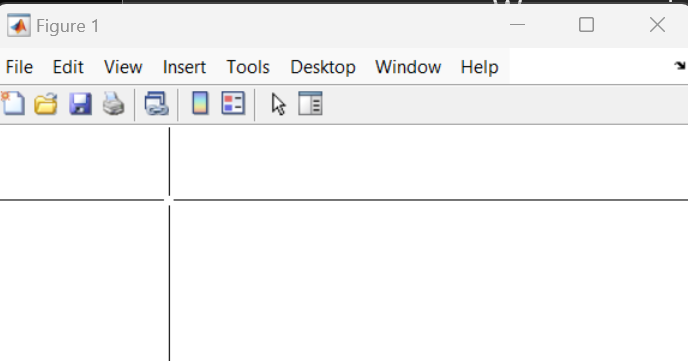

We can use `imshow` to view the image with the writing:

 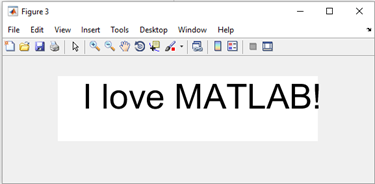

The default font size is 40, and it can be changed as the third input of the `writetext` function:

 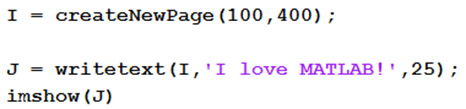

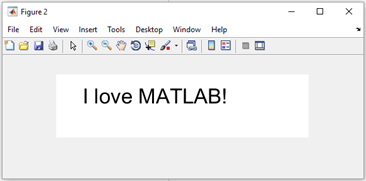

Also the color of the text can be changed using RGB values as the fourth input of the `writetext` function:

 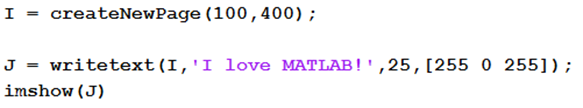

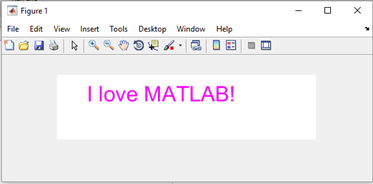

The function `createNewPage` also takes a third input which lets us change the color of the page from white to something else using RGB values again:

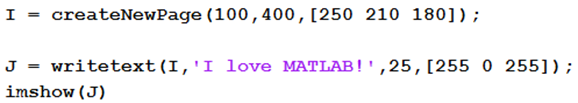

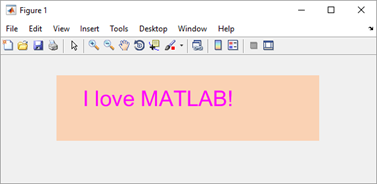

Additionally, if we do not want to keep clicking on an area of the image every time we want to write the text, we can provide a row and column location for the text to appear as the fifth input:

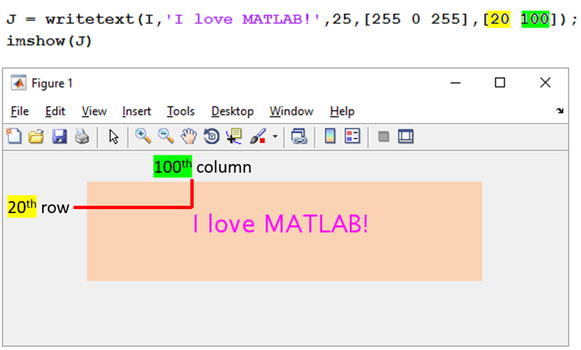

or

 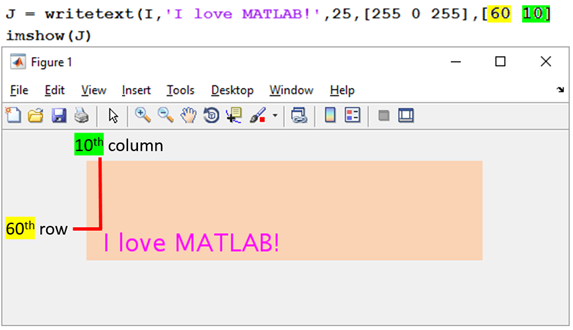

Ask the students to use the `readtext` function to check if MATLAB can read what they are writing:

 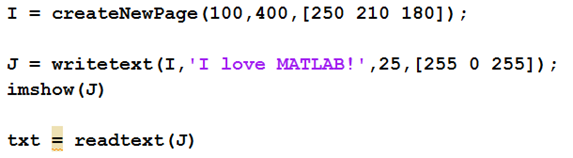

Students should explore and try to find an answer to these questions.  

Ask:

- *What will happen if you continue to decrease the font size?  *

-     Students should notice that there becomes a point where MATLAB is not able to make out the patterns correctly anymore.

- *How does the background color and font color combinations impact how well MATLAB can read the messages?  *

-     Students may notice that there are some color combinations that make it more difficult for MATLAB to read the messages. 

Tell the students that instead of using a plain background, we can actually use any image we want as background. 

In the script, comment out the first line by putting a `%` sign in front of it. Remind the students that anytime MATLAB sees anything in green it knows that it can ignore that line because it is not a command but just a comment.

Instead, read in an image of your choice and write text on it:

     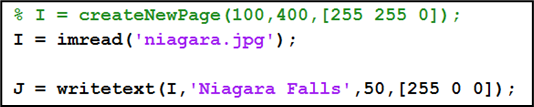

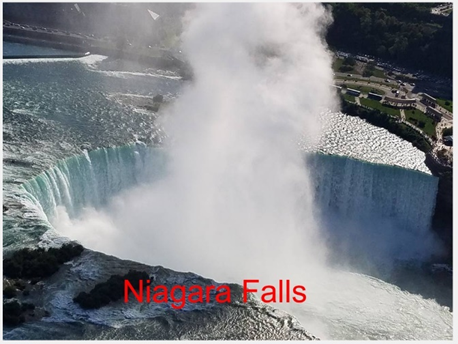

Remind the students that since the background is now no longer a solid color, the `readtext` function can no longer reliably extract the text patterns from the image.

Give the students 10 minutes to play around with the various options and create their own messages. 

Inform the students that the maximum font size allowed in an image is 200. Anything more than 200 will result in MATLAB giving an error. 

When time has expired, ask:

- *What surprises did you have while adding text?  *

-     Students may mention that they were surprised that MATLAB cannot read font sizes that are too small.

- *How might your new understanding of color and pattern recognition be helpful?  *

-     Students may mention a real-world use or perhaps a use for their final project.

© COPYRIGHT 2024 by The MathWorks®, Inc.